root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1';

% Load all .nirs files from the folder. don't have groups, just specify 'subject'
raw = nirs.io.loadDirectory(root_dir, {'subject'});

Loading : C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1\pid001
Loading C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1\pid001\2024-11-19_001.nirs
Loading NIRx file geometry from:
     C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1\pid001\
      Note: This registration will be used for all subjects
      To load all use "loadDirectory(<>,<>,@(file)nirs.io.loadNIRx(file,true))"
Loading : C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1\pid001\
Loading C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1\pid001\2024-11-19_001.nirs
Loading : C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1\pid002
Loading C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Se



nirs.createDemographicsTable(raw)

ans = 26×6 table
     subject       age        gender      contact_info     experiment       remarks  
    __________    ______    __________    ____________    _____________    __________

    {'pid001'}    {'21'}    {'Female'}     {0×0 char}     {'relmatch' }    {0×0 char}
    {'pid002'}    {'20'}    {'Female'}     {0×0 char}     {'relmatch' }    {0×0 char}
    {'pid003'}    {'23'}    {'Female'}     {0×0 char}     {'relmatch' }    {0×0 char}
    {'pid004'}    {'21'}    {'NB'    }     {0×0 char}     {'relmatch' }    {0×0 char}
    {'pid005'}    {'25'}    {'Male'  }     {0×0 char}     {'relmatch' }    {0×0 char}
    {'pid006'}    {'21'}    {'Female'}     {0×0 char}     {'rel match'}    {0×0 char}
    {'pid007'}    {'21'}    {'Female'}     {0×0 char}     {'relmatch' }    {0×0 char}
    


% Create the demographics table
demographics = nirs.createDemographicsTable(raw);

% Convert age column to numeric if it's stored as strings
numeric_age = str2double(demographics.age);

% Calculate the mean of the numeric age values
mean_age = mean(numeric_age);

% Count how many males and females in the gender column
num_males = sum(strcmp(demographics.gender, 'Male'));
num_females = sum(strcmp(demographics.gender, 'Female'));

% Display results
fprintf('Mean Age: %.2f\n', mean_age);

Mean Age: NaN


fprintf('Number of Males: %d\n', num_males);

Number of Males: 7


fprintf('Number of Females: %d\n', num_females);

Number of Females: 17



% V3 DATA Delete unwanted triggers (2, 4, 6, 7)
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'}; % Only keep these
raw = j.run(raw);
unique(nirs.getStimNames(raw))

ans = 2×1 cell array
    {'stim_channel1'}
    {'stim_channel2'}



% V3 DATA Rename Remaining Trggers 
j = nirs.modules.RemoveStimless( );
% Rename triggers 1, 3, 5,
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1'; 
    'stim_channel2', '1';
    };

% Run the renaming
raw = j.run(raw);
unique(nirs.getStimNames(raw))

ans = 1×1 cell array
    {'1'}



% Specify the new duration for each stimulus
new_duration = 36; % Duration in seconds

stimNames = unique(nirs.getStimNames(raw));
stimCount = length(stimNames);
for stimIDX = 1:stimCount
raw = nirs.design.change_stimulus_duration(raw,stimNames(stimIDX),new_duration)
end

raw = 26×1 Data array with properties:
    description
    data
    probe
    time
    Fm
    auxillary
    stimulus
    demographics
    Fs



% QT-NIRS quality assessment
j = nirs.modules.QT();
j.qThreshold = 0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

Scan 1 of 26 processed.
Scan 2 of 26 processed.
Scan 3 of 26 processed.
Scan 4 of 26 processed.
Scan 5 of 26 processed.
Scan 6 of 26 processed.
Scan 7 of 26 processed.
Scan 8 of 26 processed.
Scan 9 of 26 processed.
Scan 10 of 26 processed.
Scan 11 of 26 processed.
Scan 12 of 26 processed.
Scan 13 of 26 processed.
Scan 14 of 26 processed.
Scan 15 of 26 processed.
Scan 16 of 26 processed.
Scan 17 of 26 processed.
Scan 18 of 26 processed.
Scan 19 of 26 processed.
Scan 20 of 26 processed.
Scan 21 of 26 processed.
Scan 22 of 26 processed.
Scan 23 of 26 processed.
Scan 24 of 26 processed.
Scan 25 of 26 processed.
Scan 26 of 26 processed.



% Preprocessing
j = nirs.modules.Resample(); j.Fs = 1.5;
raw = j.run(raw);

j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

% Prune bad channels based on QT-NIRS output
Hb_pruned = hb;
for i = 1:length(hb)
    hb(i) = hb(i).sorted({'source', 'detector', 'type'});
    bad_idx = find(ScansQuality(i).qMats.MeasListAct == 0);
    fprintf('Scan: %i | #BadChannels: %i\n', i, length(bad_idx)/2);
    Hb_pruned(i).data(:, bad_idx) = NaN;
end

Scan: 1 | #BadChannels: 9
Scan: 2 | #BadChannels: 12
Scan: 3 | #BadChannels: 6
Scan: 4 | #BadChannels: 25
Scan: 5 | #BadChannels: 11
Scan: 6 | #BadChannels: 25
Scan: 7 | #BadChannels: 30
Scan: 8 | #BadChannels: 14
Scan: 9 | #BadChannels: 18
Scan: 10 | #BadChannels: 8
Scan: 11 | #BadChannels: 20
Scan: 12 | #BadChannels: 21
Scan: 13 | #BadChannels: 13
Scan: 14 | #BadChannels: 6
Scan: 15 | #BadChannels: 13
Scan: 16 | #BadChannels: 8
Scan: 17 | #BadChannels: 15
Scan: 18 | #BadChannels: 6
Scan: 19 | #BadChannels: 15
Scan: 20 | #BadChannels: 6
Scan: 21 | #BadChannels: 26
Scan: 22 | #BadChannels: 23
Scan: 23 | #BadChannels: 19
Scan: 24 | #BadChannels: 21
Scan: 25 | #BadChannels: 16
Scan: 26 | #BadChannels: 6



% label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned)

Hb_pruned = 26×1 Data array with properties:
    description
    data
    probe
    time
    Fm
    auxillary
    stimulus
    demographics
    Fs



% Apply prewhitening using AR-IRLS - no short channels 
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

.......................................................................Finished    1 of   26.
.................................................................Finished    2 of   26.
.............................................................................Finished    3 of   26.
.......................................Finished    4 of   26.
...................................................................Finished    5 of   26.
.......................................Finished    6 of   26.
.............................Finished    7 of   26.
.............................................................Finished    8 of   26.
.....................................................Finished    9 of   26.
.........................................................................Finished   10 of   26.
.................................................Finished   11 of   26.
...............................................Finished   12 of   26.
......................................................


disp(SubjStats.table());

     subject         age          gender      contact_info     experiment       remarks        scanIdx      source    detector     type      ShortSeperation     cond        beta         se         tstat        dfe          p             q         minDiscoverableChange    RelativePower
    __________    __________    __________    ____________    _____________    __________    ___________    ______    ________    _______    _______________    ______    

p3 = SubjStats.table()

p3 = 2392×20 table
     subject       age        gender      contact_info     experiment      remarks       scanIdx      source    detector     type      ShortSeperation     cond       beta        se        tstat      dfe         p             q        minDiscoverableChange    RelativePower
    __________    ______    __________    ____________    ____________    __________    __________    ______    ________    _______    _______________    ______    


% Save the table to a CSV file - change file name for session data
outputFile = '26_subject_glm_result_session1_tvr_clean.csv';            % Specify the output file name
writetable(p3, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

GLM results saved to 26_subject_glm_result_session1_tvr_clean.csv



%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, '26_subject_level_contrasts_session1_clean.csv');
disp('Contrast results saved to 26_subject_level_contrasts_session1_clean.csv');


%use chroma and channel as fixed effects not group (no group)
j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());

    source    detector     type       cond        beta          se         tstat      dfe        p             q        minDiscoverableChange    RelativePower
    ______    ________    _______    ______    __________    ________    _________    ___    __________    _________    _____________________    _____________

       1          1       {'hbo'}    {'x1'}      -0.12328     0.43714     -0.28201    25        0.78026      0.88807            1.1241              0.19852   
       1          1       {'hbr'}    {'x1'}      -0.15203     0.12539      -1.2124    25        0.23668      0.434

p4 = GroupStats.table()

p4 = 92×12 table
    source    detector     type       cond       beta          se        tstat      dfe        p           q        minDiscoverableChange    RelativePower
    ______    ________    _______    ______    _________    ________    ________    ___    _________    ________    _____________________    _____________

      1          1        {'hbo'}    {'x1'}     -0.12328     0.43714    -0.28201    25       0.78026     0.88807            1.1241              0.19852   
      1          1        {'hbr'}    {'x1'}     -0.15203     0.12539     -1.2124    25       0.23668     0.43


% Save the table to a CSV file - change file name for session data
outputFile = '26_Group_glm_result_session1_tvr_clean.csv';            % Specify the output file name
writetable(p4, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

GLM results saved to 26_Group_glm_result_session1_tvr_clean.csv


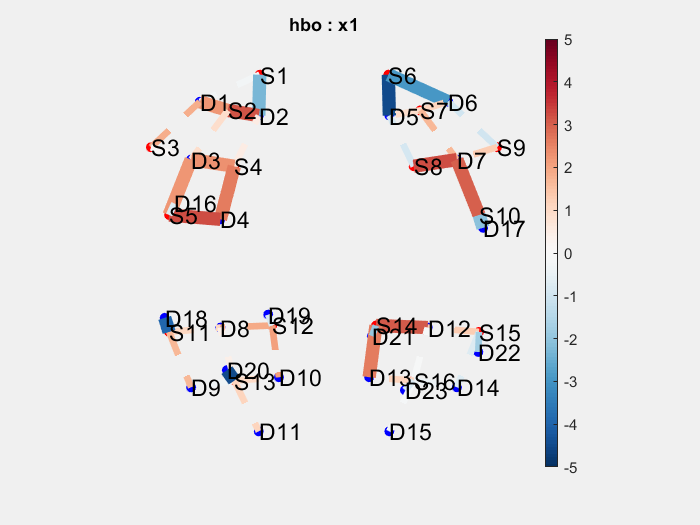

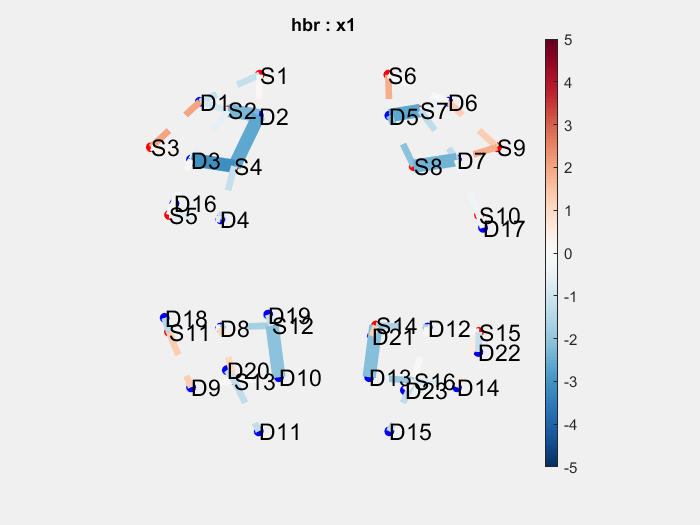

ans =   1×2 Figure array:

    Figure    Figure


GroupStats.draw('tstat', [-5 5], 'p < 0.05')


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p6 = ContrastStats2_vs_1.table()

% Save the table to a CSV file - change file name for session data
outputFile = '26_Contrast_glm_result_session1_clean.csv';            % Specify the output file name
writetable(p6, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 2';

% Load all .nirs files from the folder. don't have groups, just specify 'subject'
raw = nirs.io.loadDirectory(root_dir, {'subject'});


nirs.createDemographicsTable(raw)

% Create the demographics table
demographics = nirs.createDemographicsTable(raw);

% Convert age column to numeric if it's stored as strings
numeric_age = str2double(demographics.age);

% Calculate the mean of the numeric age values
mean_age = mean(numeric_age);

% Count how many males and females in the gender column
num_males = sum(strcmp(demographics.gender, 'Male'));
num_females = sum(strcmp(demographics.gender, 'Female'));

% Display results
fprintf('Mean Age: %.2f\n', mean_age);
fprintf('Number of Males: %d\n', num_males);
fprintf('Number of Females: %d\n', num_females);

% V3 DATA Delete unwanted triggers (2, 4, 6, 7)
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'}; % Only keep these
raw = j.run(raw);
unique(nirs.getStimNames(raw))

% V3 DATA Rename Remaining Trggers 
j = nirs.modules.RemoveStimless( );
% Rename triggers 1, 3, 5,
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1'; 
    'stim_channel2', '1';
    };

% Run the renaming
raw = j.run(raw);
unique(nirs.getStimNames(raw))

% Specify the new duration for each stimulus
new_duration = 36; % Duration in seconds

stimNames = unique(nirs.getStimNames(raw));
stimCount = length(stimNames);
for stimIDX = 1:stimCount
raw = nirs.design.change_stimulus_duration(raw,stimNames(stimIDX),new_duration)
end


%QUALITY assessment via QTNIRS job

j = nirs.modules.QT();
j.qThreshold =0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);
ScansQuality.drawGroup('sqmask');
ScansQuality.drawGroup('bar');

% Continue with the preprocessing steps
j = nirs.modules.Resample();
j.Fs = 1.5; % Resample to 2 Hz
raw = j.run(raw);

j = nirs.modules.OpticalDensity();
raw = j.run(raw);

%motion correction
j = nirs.modules.TDDR();
%j.usePCA = 'true';
raw = j.run(raw);

j = nirs.modules.BeerLambertLaw();
hb = j.run(raw);

%CHANNEL PRUNING based on QTNIRS results
Hb_pruned = hb;
for i=1:length(raw)
   hb(i) = hb(i).sorted({'source', 'detector', 'type'});
   idxBadCh = find(ScansQuality(i).qMats.MeasListAct==0);
   fprintf('Scan:%i #BadChannels:%i\n',i,length(idxBadCh)/2);
   Hb_pruned(i).data(:,idxBadCh) = nan;
end

% label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned)

% --- ROI Aggregation ---
roi_definitions = struct( ...
    'Left_RLPFC', [1 1; 1 2; 2 1; 2 2], ...
    'Left_DLPFC', [4 3; 4 2; 4 4; 5 3; 5 4; 2 3], ...
    'Left_VLPFC', [3 1; 3 3], ...
    'Left_Sup_Parietal', [12 8; 12 10; 13 10], ...
    'Left_Inf_Parietal', [11 9; 11 8; 13 8; 13 9; 13 11], ...
    'Right_RLPFC', [6 5; 6 6; 7 5; 7 6], ...
    'Right_DLPFC', [7 7; 8 5; 8 7; 10 7; 10 17], ...
    'Right_VLPFC', [9 7; 9 6], ...
    'Right_Sup_Parietal', [14 12; 14 13;16 13], ...
    'Right_Inf_Parietal', [15 12; 15 14; 16 12; 16 14; 16 15] ...
);

% ROI-specific dummy source-detector assignments for proper plotting
roi_sd_lookup = struct( ...
    'Left_RLPFC', [2, 2], ...
    'Left_DLPFC', [4, 3], ...
    'Left_VLPFC', [3, 1], ...
    'Left_Sup_Parietal', [12, 10], ...
    'Left_Inf_Parietal', [11, 9], ...
    'Right_RLPFC', [7, 5], ...
    'Right_DLPFC', [8, 7], ...
    'Right_VLPFC', [9, 6], ...
    'Right_Sup_Parietal', [14, 13], ...
    'Right_Inf_Parietal', [15, 14] ...
);

for i = 1:length(Hb_pruned)
    dat = Hb_pruned(i);
    new_data = [];
    roi_labels = {};
    sources = [];
    detectors = [];

    for roi = fieldnames(roi_definitions)'
        roi_name = roi{1};
        pairs = roi_definitions.(roi_name);
        roi_ts = nan(size(dat.data, 1), size(pairs, 1));

        for p = 1:size(pairs, 1)
            src = pairs(p, 1);
            det = pairs(p, 2);
            idx = find(dat.probe.link.source == src & ...
                       dat.probe.link.detector == det & ...
                       strcmpi(dat.probe.link.type, 'hbo'));
            if ~isempty(idx)
                roi_ts(:, p) = dat.data(:, idx(1));
            end
        end

        % Average across channels in the ROI
        new_data = [new_data, nanmean(roi_ts, 2)];
        roi_labels = [roi_labels, roi_name];

        % Use fixed dummy source-detector pair
        sources(end+1) = roi_sd_lookup.(roi_name)(1);
        detectors(end+1) = roi_sd_lookup.(roi_name)(2);
    end

    % Replace data with aggregated ROI signals
    dat.data = new_data;

    % Construct new probe link table with correct dummy S-D mapping
    new_link = table();
    new_link.source = sources';
    new_link.detector = detectors';
    new_link.type = repmat({'hbo'}, length(roi_labels), 1);
    new_link.name = roi_labels';
    dat.probe.link = new_link;

    Hb_pruned(i) = dat;
end


% Apply prewhitening using AR-IRLS 
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

disp(SubjStats.table());
p3 = SubjStats.table()

% Save the table to a CSV file - change file name for session data
outputFile = '26_subject_glm_result_ROI_AGG_session2_tvr_clean.csv';            % Specify the output file name
writetable(p3, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector


contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, '26_subject_level_contrasts_ROI_AGG_session2_clean.csv');
disp('Contrast results saved to 26_subject_level_contrasts_ROI_AGG_session1tvr.csv');


%use chroma and channel as fixed effects not group (no group)
j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p4 = GroupStats.table()

% Save the table to a CSV file - change file name for session data
outputFile = '26_Group_glm_result_ROI_AGG_session2_tvr_clean.csv';            % Specify the output file name
writetable(p4, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);
GroupStats.draw('tstat', [-5 5], 'p < 0.05')


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p6 = ContrastStats2_vs_1.table()

% Save the table to a CSV file - change file name for session data
outputFile = '26_Contrast_glm_result_ROI_AGG_session2_clean.csv';            % Specify the output file name
writetable(p6, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);


% Loop through each subject and condition to display GLM t-stat figures
for i = 1:length(SubjStats)
    subj = SubjStats(i);
    subj_name = strrep(subj.description, filesep, '_'); % Clean subject name for figure title
    
    % Get list of all conditions (e.g., '1', '2') from the subject's stim list
    stimNames = unique(nirs.getStimNames(hb(i)));

    for s = 1:length(stimNames)
        % Build contrast vector: 1 for this condition, 0 for others
        num_conds = length(stimNames);
        contrast_vec = zeros(1, num_conds);
        contrast_vec(s) = 1;

        % Run t-test for this condition vs. baseline
        contrast_stats = subj.ttest(contrast_vec);

        % Display figure
        figure;
        contrast_stats.draw('tstat', [-5 5], 'q < 0.05');
        title(sprintf('Subject: %s | Condition: %s', subj_name, stimNames{s}), 'Interpreter', 'none');
    end
end

% Contrast Pipeline 

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 2';

% Load all .nirs files from the folder. don't have groups, just specify 'subject'
raw = nirs.io.loadDirectory(root_dir, {'subject'});


nirs.createDemographicsTable(raw)

% Create the demographics table
demographics = nirs.createDemographicsTable(raw);

% Convert age column to numeric if it's stored as strings
numeric_age = str2double(demographics.age);

% Calculate the mean of the numeric age values
mean_age = mean(numeric_age);

% Count how many males and females in the gender column
num_males = sum(strcmp(demographics.gender, 'Male'));
num_females = sum(strcmp(demographics.gender, 'Female'));

% Display results
fprintf('Mean Age: %.2f\n', mean_age);
fprintf('Number of Males: %d\n', num_males);
fprintf('Number of Females: %d\n', num_females);

% V3 DATA Delete unwanted triggers (2, 4, 6, 7)
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'}; % Only keep these
raw = j.run(raw);
unique(nirs.getStimNames(raw))

% V3 DATA Rename Remaining Trggers 
j = nirs.modules.RemoveStimless( );
% Rename triggers 1, 3, 5,
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1'; 
    'stim_channel2', '2';
    };

% Run the renaming
raw = j.run(raw);
unique(nirs.getStimNames(raw))

% Specify the new duration for each stimulus
new_duration = 36; % Duration in seconds

stimNames = unique(nirs.getStimNames(raw));
stimCount = length(stimNames);
for stimIDX = 1:stimCount
raw = nirs.design.change_stimulus_duration(raw,stimNames(stimIDX),new_duration)
end
% Continue with the preprocessing steps
j = nirs.modules.Resample();
j.Fs = 1.4; % Resample to 1 Hz
raw = j.run(raw);

j = nirs.modules.OpticalDensity();
raw = j.run(raw);

%motion correction
j = nirs.modules.TDDR();
%j.usePCA = 'true';
raw = j.run(raw);

j = nirs.modules.BeerLambertLaw();
hb = j.run(raw);

% label short channels
j = nirs.modules.LabelShortSeperation();
hb = j.run(hb)

% Initialize AR-IRLS GLM module 
glm_job = nirs.modules.AR_IRLS();

% Loop over each subject in the hb data
for i = 1:length(hb)
    fprintf('Running GLM for subject %d\n', i);
    
    % Run subject-level GLM
    subjGLM = glm_job.run(hb(i));
    
    % Define the contrast vector: Condition 2 vs Condition 1
    contrast_vec = [-1, 1, 0];  % Assumes design matrix: [Cond1, Cond2, Baseline or similar]
    
    % Apply the contrast
    contrast_stats = subjGLM.ttest(contrast_vec);

    % Extract channel names and chromophores
    linkTable = contrast_stats.probe.link;
    channel_names = strcat('S', string(linkTable.source), '_D', string(linkTable.detector));
    chromophores = string(linkTable.type);

    % Save or extract statistics
    t_values{i} = contrast_stats.tstat;
    beta_values{i} = contrast_stats.beta;
    p_values{i} = contrast_stats.p;
    description{i} = string(hb(i).description);  % Use full file path
    subject_ids{i} = repmat(description{i}, length(beta_values{i}), 1);
    channels{i} = channel_names;
    chroma{i} = chromophores;

    % Optional: Plot for visualization
    figure;
    contrast_stats.draw('tstat', [-5 5], 'p < 0.05');
    title(sprintf('Subject %s: Condition 2 > Condition 1', description{i}));
end

% Combine into a summary table
for i = 1:length(hb)
    T = table(subject_ids{i}, channels{i}, chroma{i}, beta_values{i}, t_values{i}, p_values{i}, ...
        'VariableNames', {'SubjectID', 'Channel', 'Chromophore', 'Beta', 'T', 'P'});

    if i == 1
        AllStats = T;
    else
        AllStats = [AllStats; T];
    end
end

% Save the combined table
writetable(AllStats, 'group_subject_level_contrasts_session2.csv');

% Entire Timeseries Correlations (no stim blocks)
root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\Session to Session Data\nirs\Session 1';

% Load all .nirs files from the folder. don't have groups, just specify 'subject'
raw = nirs.io.loadDirectory(root_dir, {'subject'});


nirs.createDemographicsTable(raw)

% Create the demographics table
demographics = nirs.createDemographicsTable(raw);

% Convert age column to numeric if it's stored as strings
numeric_age = str2double(demographics.age);

% Calculate the mean of the numeric age values
mean_age = mean(numeric_age);

% Count how many males and females in the gender column
num_males = sum(strcmp(demographics.gender, 'Male'));
num_females = sum(strcmp(demographics.gender, 'Female'));

% Display results
fprintf('Mean Age: %.2f\n', mean_age);
fprintf('Number of Males: %d\n', num_males);
fprintf('Number of Females: %d\n', num_females);

% V3 DATA Delete unwanted triggers (2, 4, 6, 7)
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'}; % Only keep these
raw = j.run(raw);
unique(nirs.getStimNames(raw))

% V3 DATA Rename Remaining Trggers 
j = nirs.modules.RemoveStimless( );
% Rename triggers 1, 3, 5,
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1'; 
    'stim_channel2', '1';
    };

% Run the renaming
raw = j.run(raw);
unique(nirs.getStimNames(raw))

% Specify the new duration for each stimulus
new_duration = 36; % Duration in seconds

stimNames = unique(nirs.getStimNames(raw));
stimCount = length(stimNames);
for stimIDX = 1:stimCount
raw = nirs.design.change_stimulus_duration(raw,stimNames(stimIDX),new_duration)
end

% Continue with the preprocessing steps
j = nirs.modules.Resample();
j.Fs = 1.4; % Resample to 2 Hz
raw = j.run(raw);

j = nirs.modules.OpticalDensity();
raw = j.run(raw);

%motion correction
j = nirs.modules.TDDR();
%j.usePCA = 'true';
raw = j.run(raw);

j = nirs.modules.BeerLambertLaw();
hb = j.run(raw);

% label short channels
j = nirs.modules.LabelShortSeperation();
hb = j.run(hb)

% Apply prewhitening using AR-IRLS 
j = nirs.modules.AR_IRLS();
SubjStats = j.run(hb);

disp(SubjStats.table());
p3 = SubjStats.table()

% Loop through each subject and condition to display GLM t-stat figures
for i = 1:length(SubjStats)
    subj = SubjStats(i);
    subj_name = strrep(subj.description, filesep, '_'); % Clean subject name for figure title
    
    % Get list of all conditions (e.g., '1', '2') from the subject's stim list
    stimNames = unique(nirs.getStimNames(hb(i)));

    for s = 1:length(stimNames)
        % Build contrast vector: 1 for this condition, 0 for others
        num_conds = length(stimNames);
        contrast_vec = zeros(1, num_conds);
        contrast_vec(s) = 1;

        % Run t-test for this condition vs. baseline
        contrast_stats = subj.ttest(contrast_vec);

        % Display figure
        figure;
        contrast_stats.draw('tstat', [-5 5], 'q < 0.05');
        title(sprintf('Subject: %s | Condition: %s', subj_name, stimNames{s}), 'Interpreter', 'none');
    end
end

% Save the table to a CSV file - change file name for session data
outputFile = 'fulltimeseries_session1.csv';            % Specify the output file name
writetable(p3, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

%use chroma and channel as fixed effects not group (no group)
j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

GroupStats.draw('tstat', [-5 5], 'p < 0.05')

% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');